# Draw the transformation

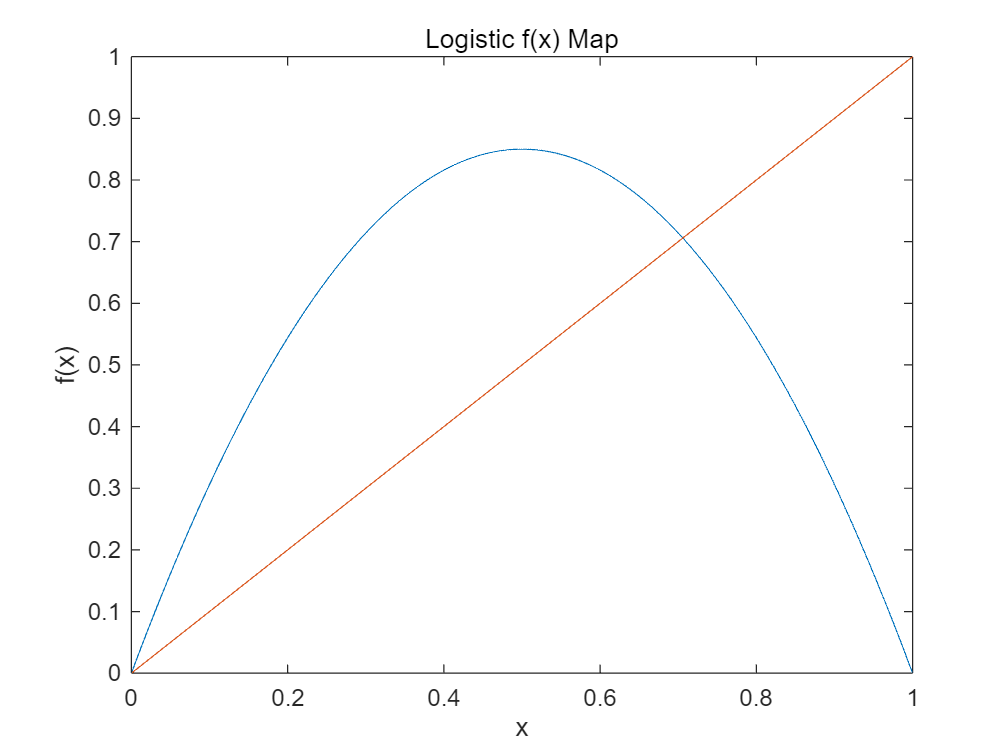

r = 3.4;
f = @(x) logisticF(r, x);
ff = @(x) f(f(x));

x_star = 1 - (1/r);
alpha = 1 / (1 - 2 * x_star);

Tf = @(x) alpha * (ff(x / alpha + x_star) - x_star);

xx = 0:0.0005:1;
figf = f(xx);
figff = ff(xx);
figTf = Tf(xx);

dd = [0 1];
xy = [0 1 0 1];
figure
plot(xx, figf, dd, dd)
axis(xy)
xlabel("x")
ylabel("f(x)")
title("Logistic f(x) Map")

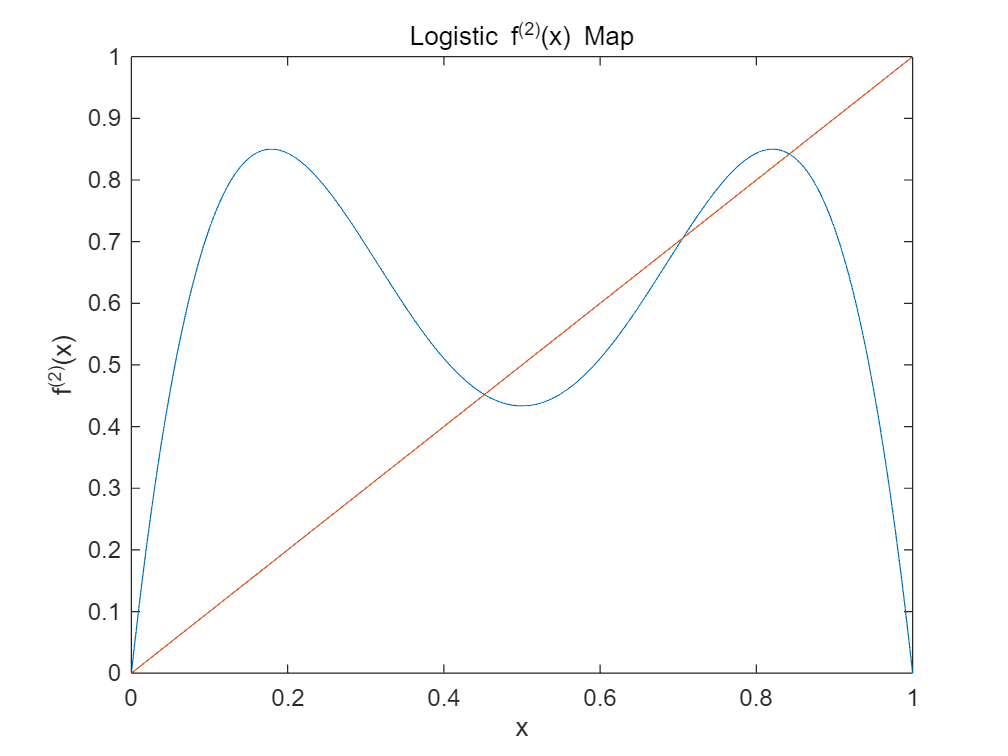


figure
plot(xx, figff, dd, dd)
axis(xy)
xlabel("x")
ylabel("f^{(2)}(x)")
title("Logistic f^{(2)}(x) Map")

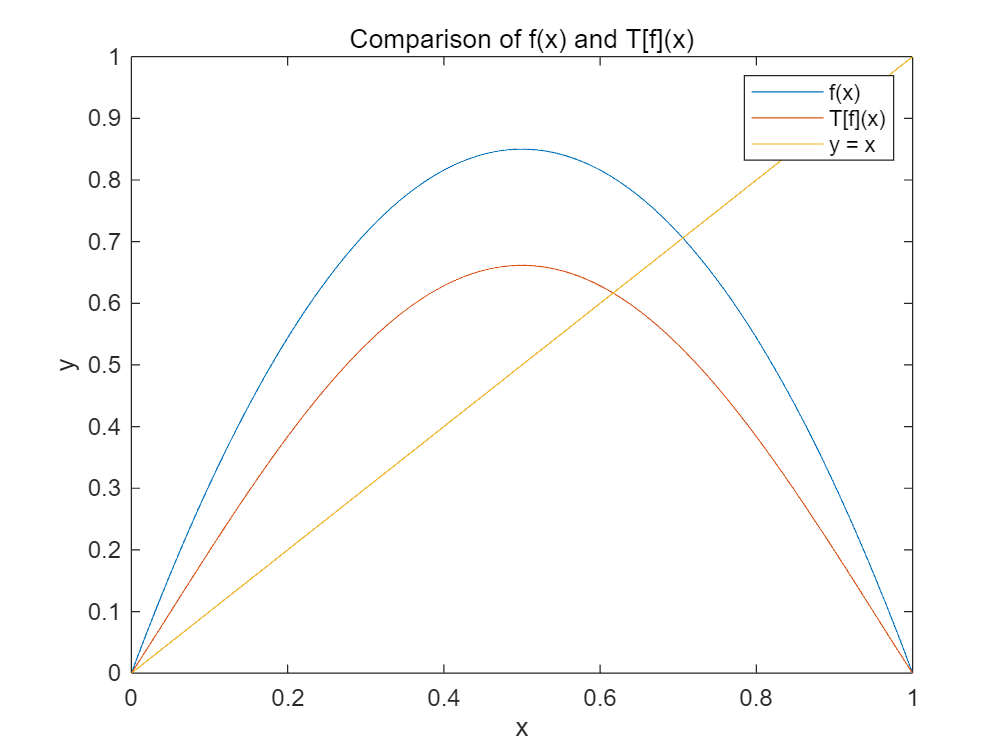


figure
plot(xx, figf, xx, figTf, dd, dd)
legend("f(x)", "T[f](x)", "y = x")
axis(xy)
xlabel("x")
ylabel("y")
title("Comparison of f(x) and T[f](x)")

# Find the universal function g that T[g] = g

method:

T[g] = \alpha * g(g(x/\alpha))

Introduce a boundary to make sure that T[g]=g have a determined solution -> Assume g =

C_0 + C_2 x^2 + C_4 x^4 + ...

Substitute this into T[g]=g and solve for C_2i.

Let C_0 = 1.

function [C, alpha] = solve_universal(N, initial_guess)
    % N：截断阶数，最高项为x^(2N)
    % initial_guess：[alpha; C2; C4; ...; C2N]

    syms x real;
    vars = sym('C', [N+1, 1]);
    alpha_sym = vars(1);
    C_sym = vars(2:end);
    C0 = 1;

    g = C0;
    for i = 1:N
        g = g + C_sym(i) * x^(2*i);
    end

    y = x/alpha_sym;
    gy = subs(g, x, y);
    ggy = subs(g, x, gy);
    Tg = alpha_sym * ggy;
    Tg_expand = collect(expand(Tg));

    coeffs_Tg = coeffs(Tg_expand, x);
    coeffs_Tg = coeffs_Tg(1:N+1);

    eqs = sym(zeros(N+1, 1));
    for k = 0:N
        coeff_val = coeffs_Tg(k+1);
        if k == 0
            eqs(1) = coeff_val - C0;
        else
            eqs(k+1) = coeff_val - C_sym(k);
        end
    end

    fun = matlabFunction(eqs, 'Vars', {vars});
    options = optimoptions('fsolve', 'Display', 'iter', 'Algorithm', 'levenberg-marquardt');
    sol = fsolve(fun, initial_guess, options);
    alpha = sol(1);
    C = [C0; sol(2:end)];
end

N = 7;
initial_guess = [-2.5; -1.5; -0.1; 0.1; 0.1; 0.1; 0.1; 0.1];
[C, alpha] = solve_universal(N, initial_guess);


                                        First-order                     Norm of 
 Iteration  Func-count   ||f(x)||^2      optimality       Lambda           step
     0           9          25.1113             108         0.01
     1          18        0.0104941            1.78        0.001       0.270129
     2          27      1.65246e-05          0.0318       0.0001       0.125574
     3          36      2.69538e-06         0.00352        1e-05       0.113654
     4          45      1.82694e-09        0.000809        1e-06      0.0182417
     5          54      4.73234e-16        4.03e-07        1e-07    0.000298936
     6          63      2.27058e-24        2.54e-13        1e-08    4.07751e-07

方程已解。

fsolve 已完成，因为按照函数容差的值衡量，
函数值向量接近于零，并且按照梯度的值衡量，
问题似乎为正则问题。


for i = 0:N
    fprintf('C_%d = %.6f\n', 2*i, C(i+1));
end

C_0 = 1.000000
C_2 = -1.527633
C_4 = 0.104814
C_6 = 0.026707
C_8 = -0.003528
C_10 = 0.000082
C_12 = 0.000025
C_14 = -0.000002


fprintf('alpha = %.6f\n', alpha);

alpha = -2.502907


# Paint g

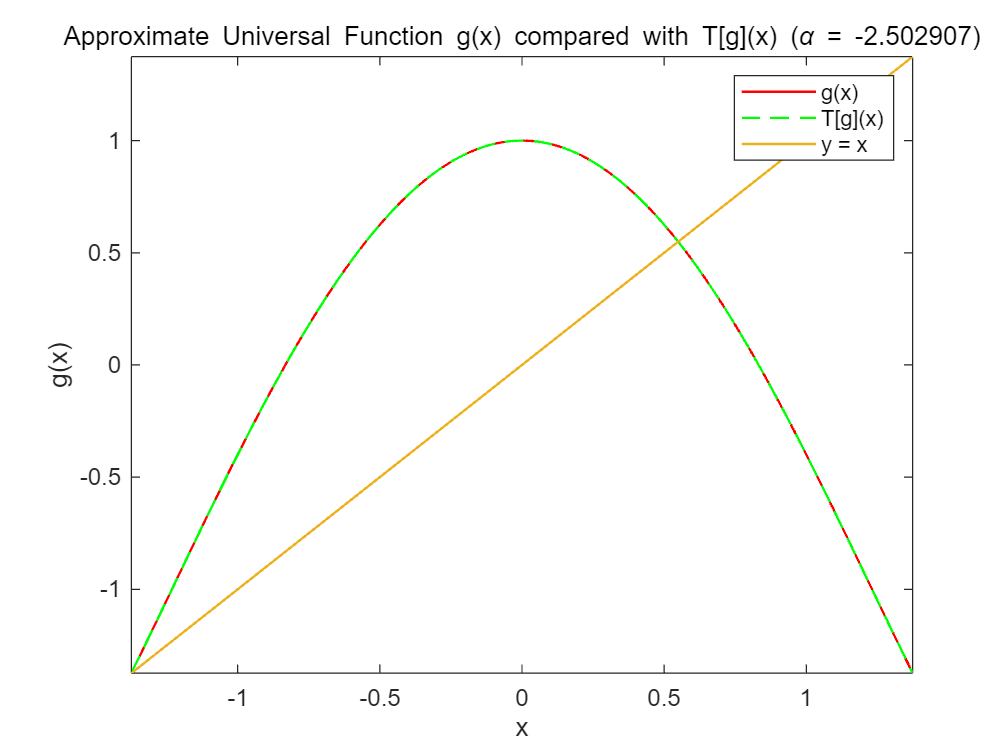

xx = linspace(-1.374, 1.374, 1000);
gg = zeros(size(xx));
for i = 0:N
    gg = gg + C(i+1) * xx.^(2*i);
end

% 计算 T[g] = alpha * g(g(x/alpha))
y = xx / alpha; % x/alpha
gy = zeros(size(y));
for i = 0:N
    gy = gy + C(i+1) * y.^(2*i); % g(y) = g(x/alpha)
end

ggy = zeros(size(gy));
for i = 0:N
    ggy = ggy + C(i+1) * gy.^(2*i); % g(g(y)) = g(g(x/alpha))
end

Tg = alpha * ggy;

dd = [-1.374 1.374];

figure
plot(xx, gg, 'r', xx, Tg, '--g', dd, dd, LineWidth=1)
axis([dd dd])
xlabel("x")
ylabel("g(x)")
legend('g(x)', 'T[g](x)', 'y = x')
title("Approximate Universal Function g(x) compared with T[g](x) (\alpha = -2.502907)")